## Q1 - Simulation Report

### part a)

Diagram of the left topology:

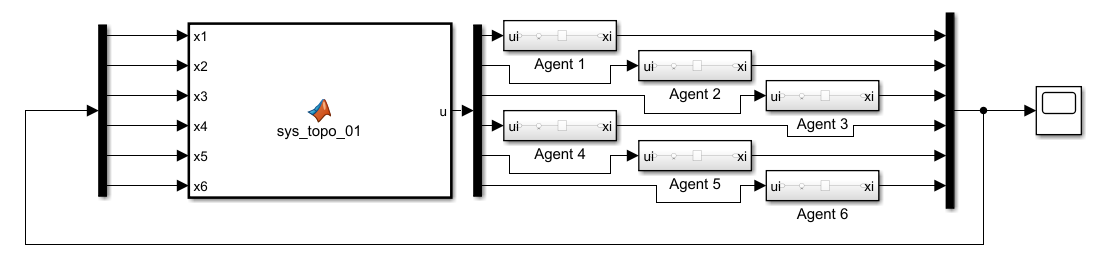

Each agent dynamics is implemented as follows:

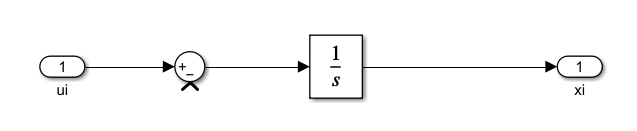

The MAS dynamics could be implemented as follows. First, laplacian matrix is formed based on the given topology. Then the control signal is generated using `U = -LX.`

function u = sys_topo_01(x1, x2, x3, x4, x5, x6)

L = [ 0  0  0  0  0  0;
     -1 +1  0  0  0  0;
      0 -1 +1  0  0  0;
      0  0 -1 +1  0  0;
      0  0 -1 -1 +2  0;
      0  0  0  0 -1 +1;
    ];

states = [x1, x2, x3, x4, x5, x6]';

u = -L*states;

end

Note that the initial conditions of the agents are set as follows: 10 , 1 , 2 , 3 , 4 , 5

The consensus is reached as in the following figure.

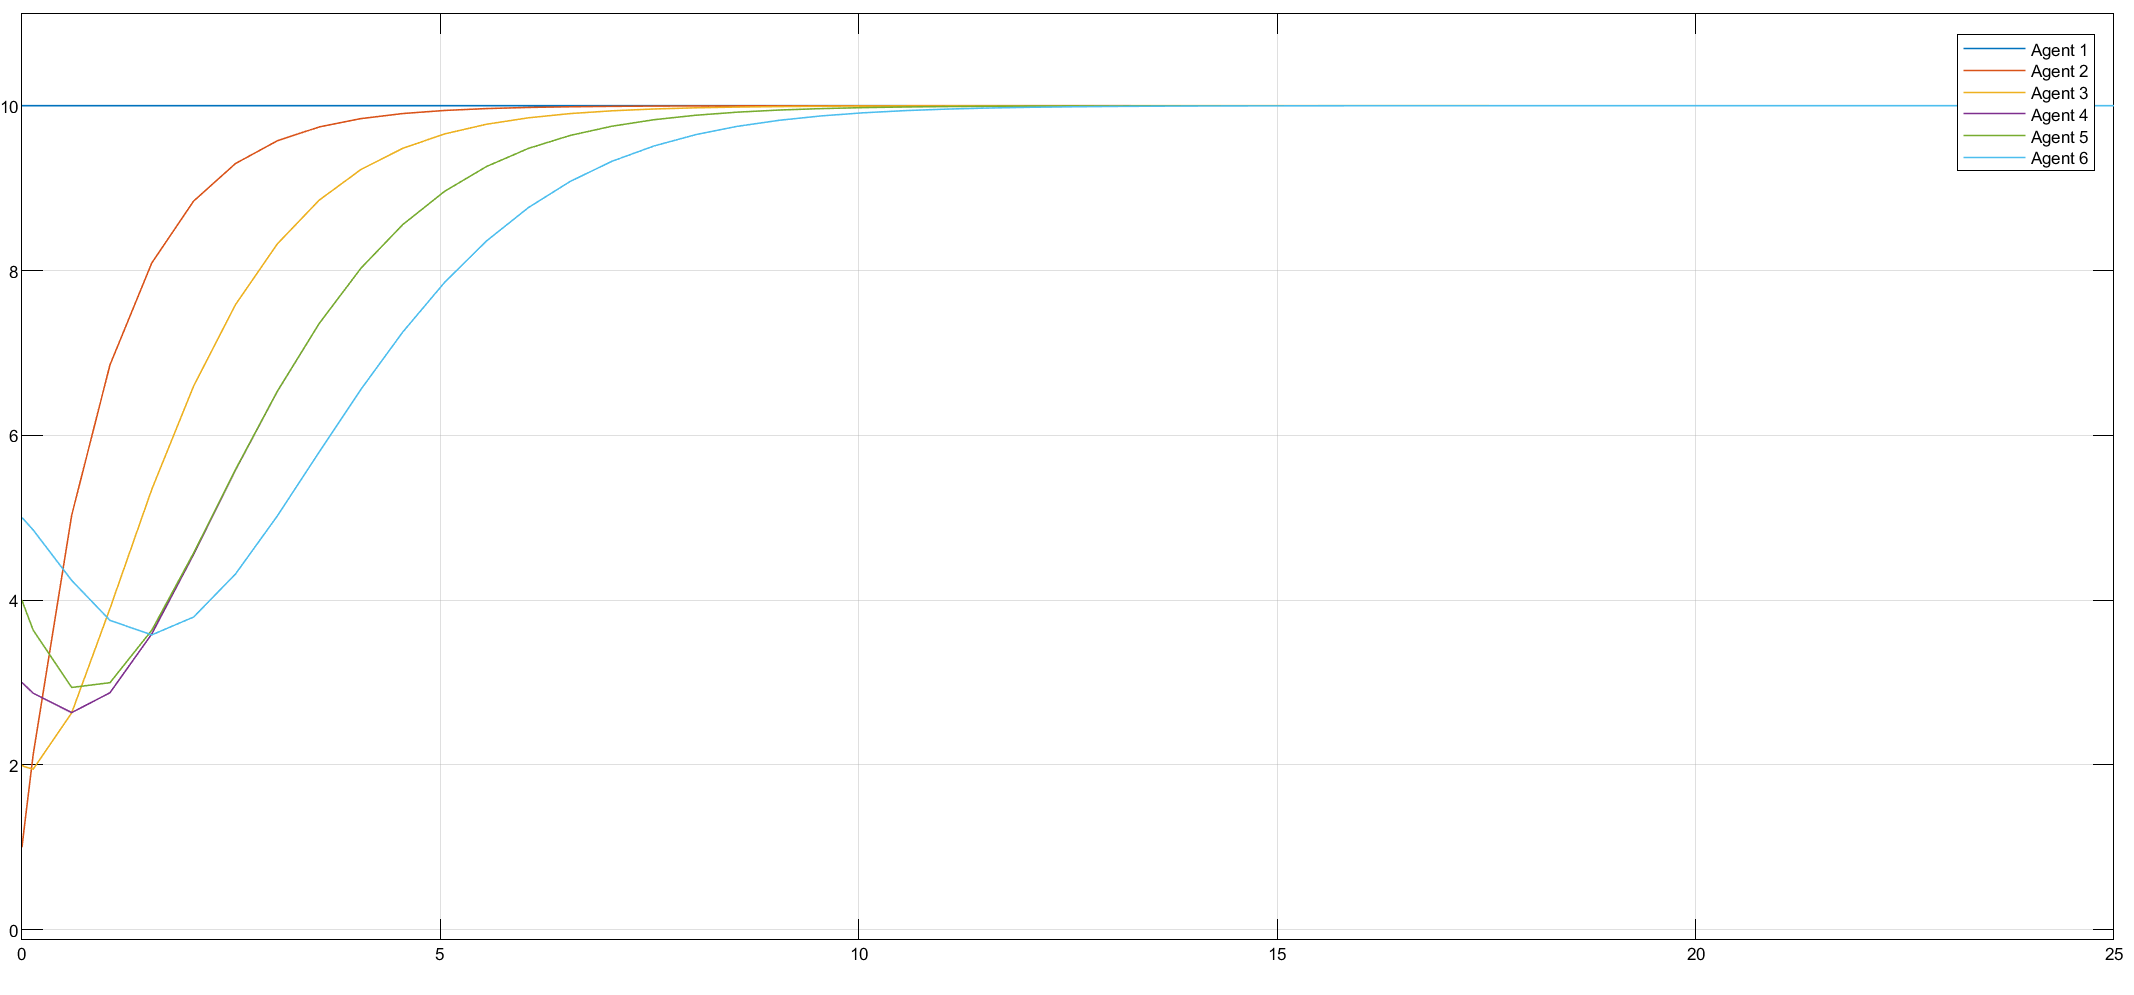

Diagram of the right topology:

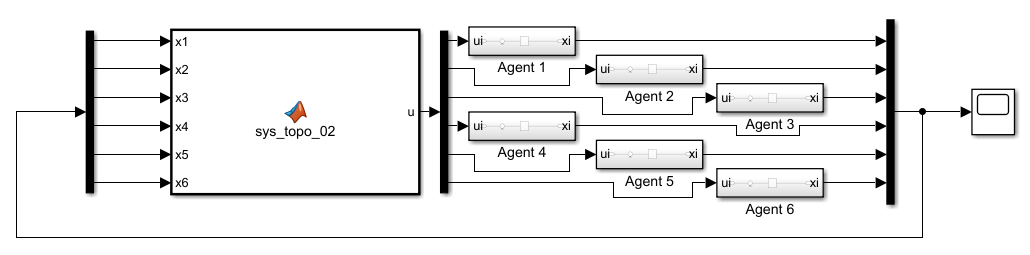

Each agent dynamics is implemented as follows:

The MAS dynamics could be implemented as follows. First, laplacian matrix is formed based on the given topology. Then the control signal is generated using `U = -LX.`

function u = sys_topo_02(x1, x2, x3, x4, x5, x6)

L = [+1  0  0  0  0 -1;
     -1 +1  0  0  0  0;
      0 -1 +1  0  0  0;
      0  0 -1 +1  0  0;
      0  0  0 -1 +1  0;
      0  0  0  0 -1 +1;
       ];

states = [x1, x2, x3, x4, x5, x6]';

u = -L*states;

end

Note that the initial conditions of the agents are set as follows: 10 , 1 , 2 , 3 , 4 , 5

The consensus is reached as in the following figure.

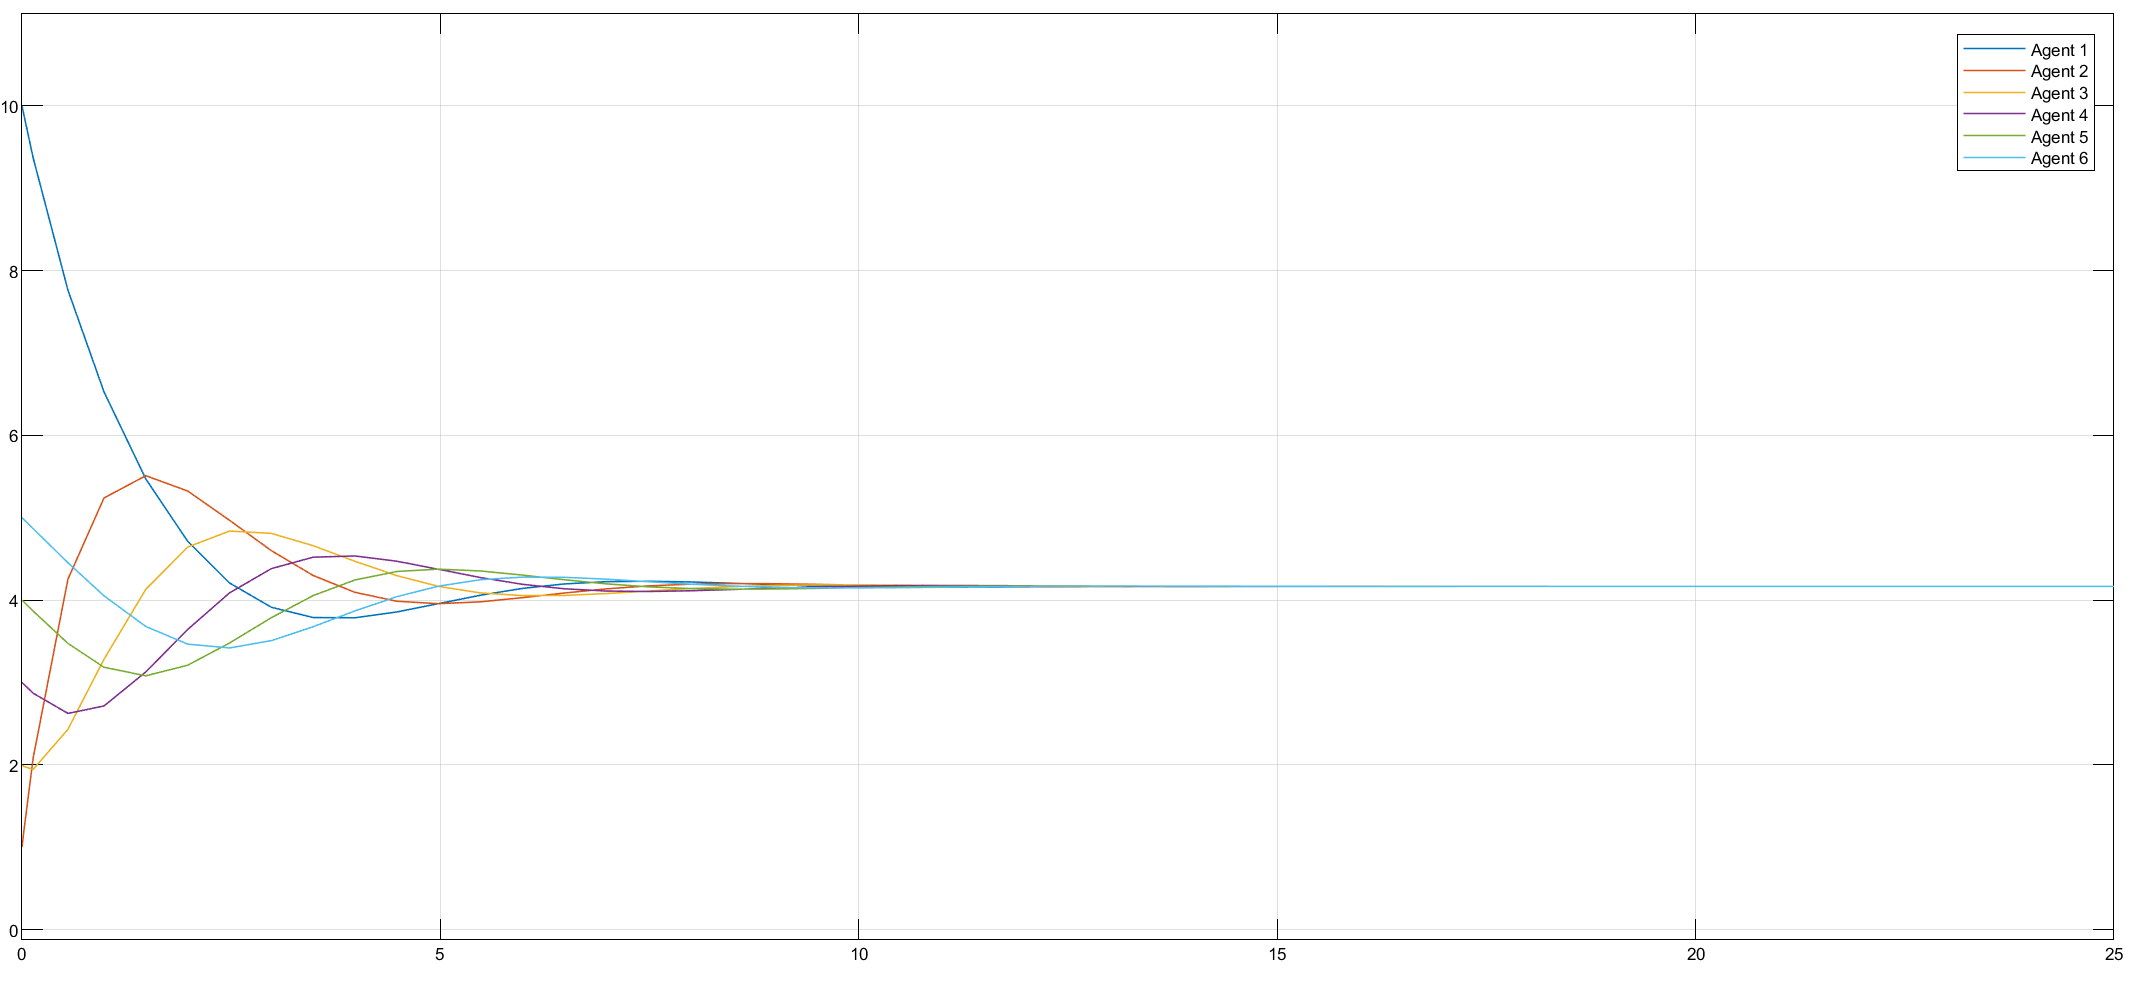

### part b)

Diagram of the left topology:

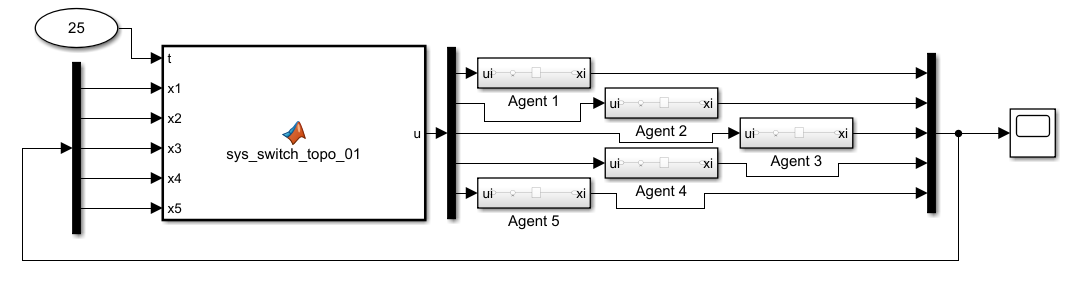

Each agent dynamics is implemented as follows:

The MAS dynamics could be implemented as follows. First, laplacian matrix is formed based on the given topology. Then the control signal is generated using `U = -LX`

In order to switch between topologies every 2s, we could use the `clock` block to access the simulation time. Therefore, passing the time into the function enables us to switch between topologies at any desired time using simple `if` statements.   

function u = sys_switch_topo_01(t, x1, x2, x3, x4, x5)

if rem(floor(t/2),2) == 0
    L = [1  0  0  0 -1;
         0  0  0  0  0;
        -1 -1 +2  0  0;
         0  0  0  0  0;
         0  0  0  0  0;
        ];

else
    L = [1  0  0  0 -1;
         0 +1 -1  0  0;
         0  0  0  0  0;
         0  0 -1 +1  0;
         0  0  0  0  0;
        ];
end
    
states = [x1, x2, x3, x4 x5]';

u = -L*states;

end

Note that the initial conditions of the agents are set as follows: 4 , 1 , 2 , 3 , 10

The consensus is reached as in the following figure.

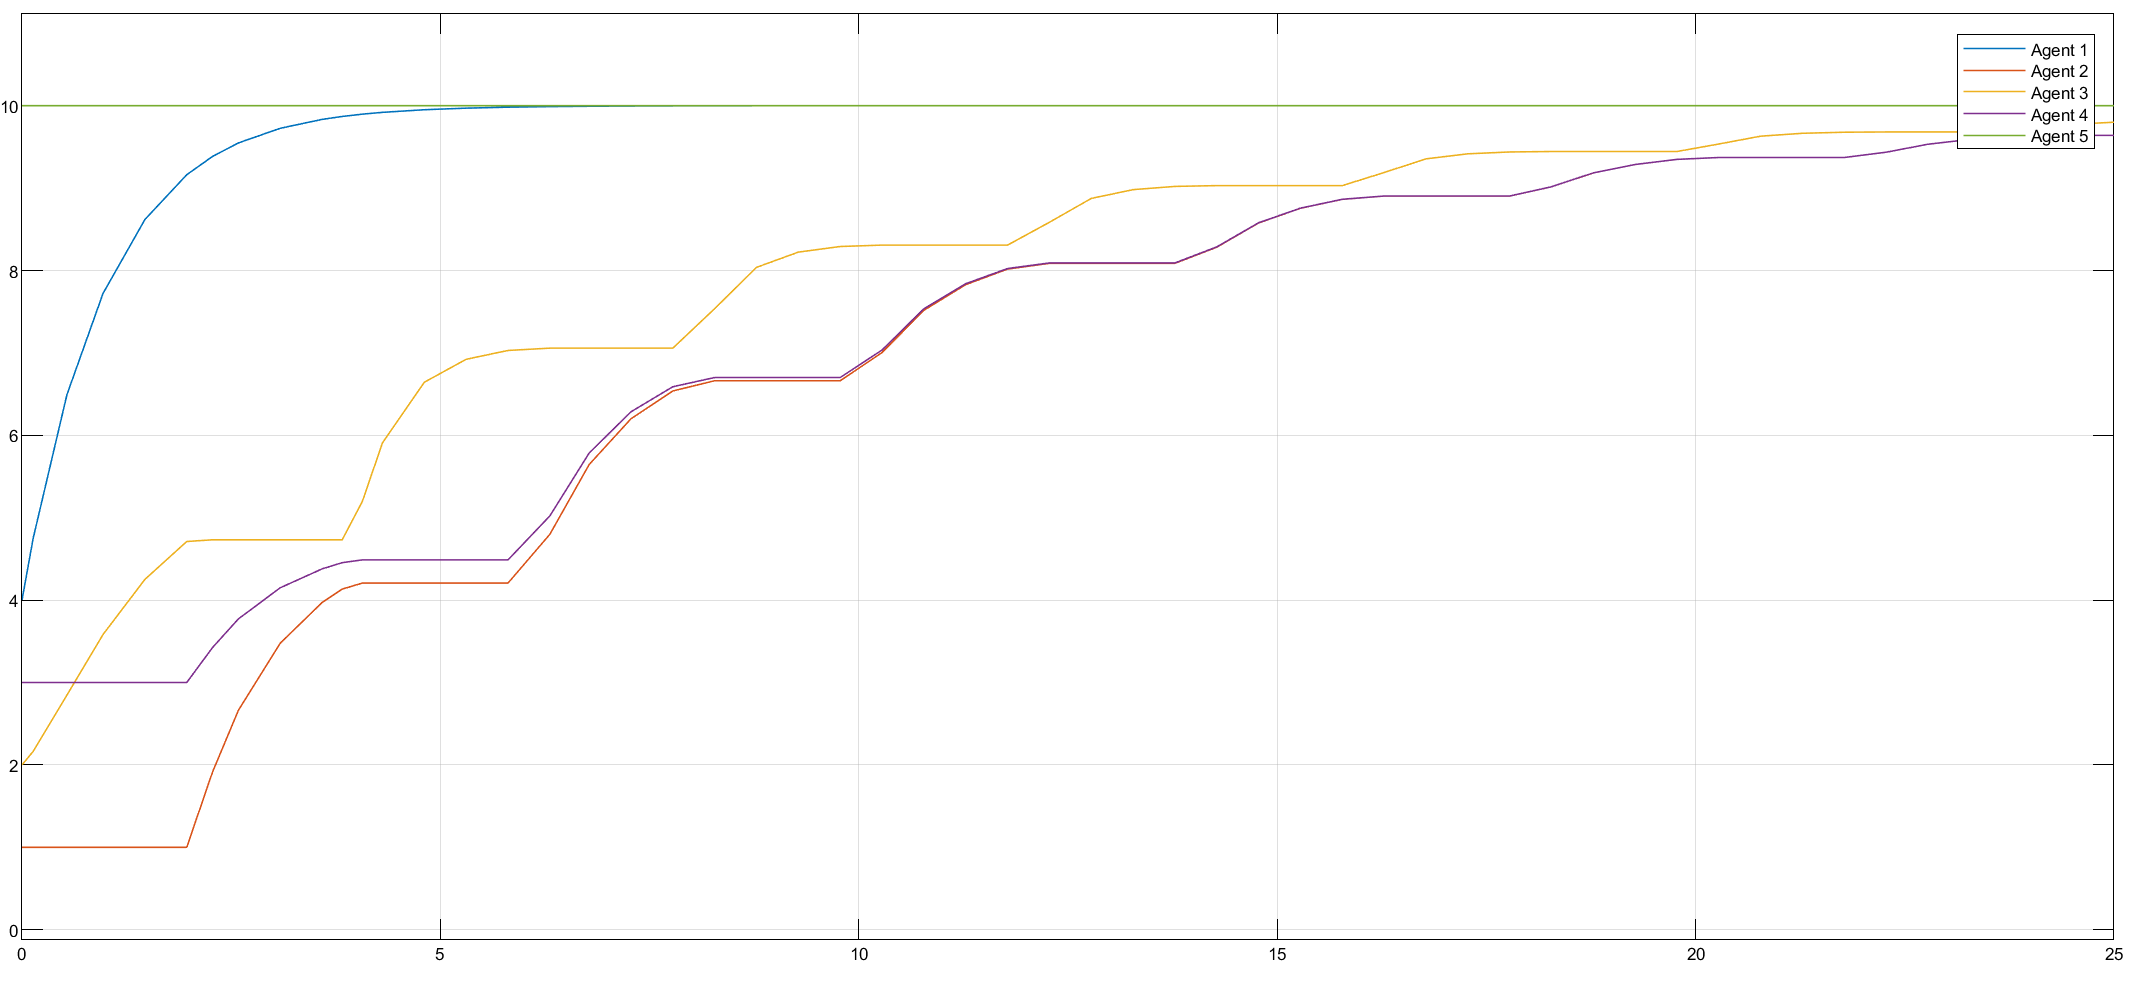

Diagram of the right topology:

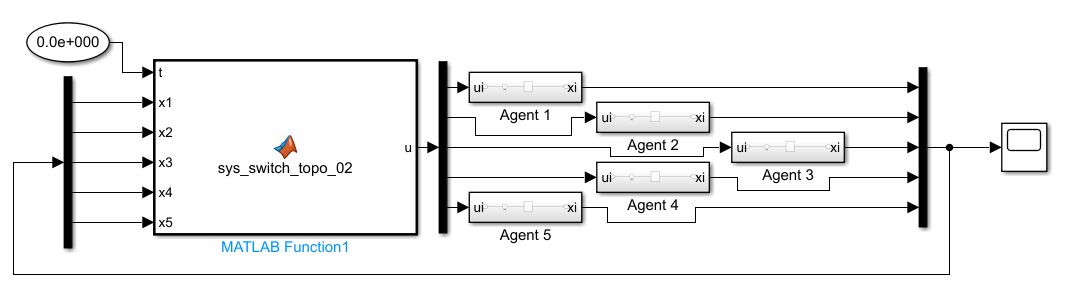

Each agent dynamics is implemented as follows:

The MAS dynamics could be implemented as follows. First, laplacian matrix is formed based on the given topology. Then the control signal is generated using `U = -LX`

In order to switch between topologies every 2s, we could use the `clock` block to access the simulation time. Therefore, passing the time into the function enables us to switch between topologies at any desired time using simple `if` statements.   

function u = sys_switch_topo_02(t, x1, x2, x3, x4, x5)

if rem(floor(t/2),2) == 0
    L = [2  0 -1  0 -1;
         0  0  0  0  0;
         0  0  0  0  0;
         0  0 -1 +1  0;
         0  0  0  0  0;
        ];

else
    L = [2 -1  0  0 -1;
         0  0  0  0  0;
         0  0  0  0  0;
         0 -1  0 +1  0;
         0  0  0  0  0;
        ];
end
    
states = [x1, x2, x3, x4 x5]';

u = -L*states;

end

Note that the initial conditions of the agents are set as follows: 4 , 1 , 2 , 3 , 10

As there is no jointly connected tree (spanning tree) in the topology.

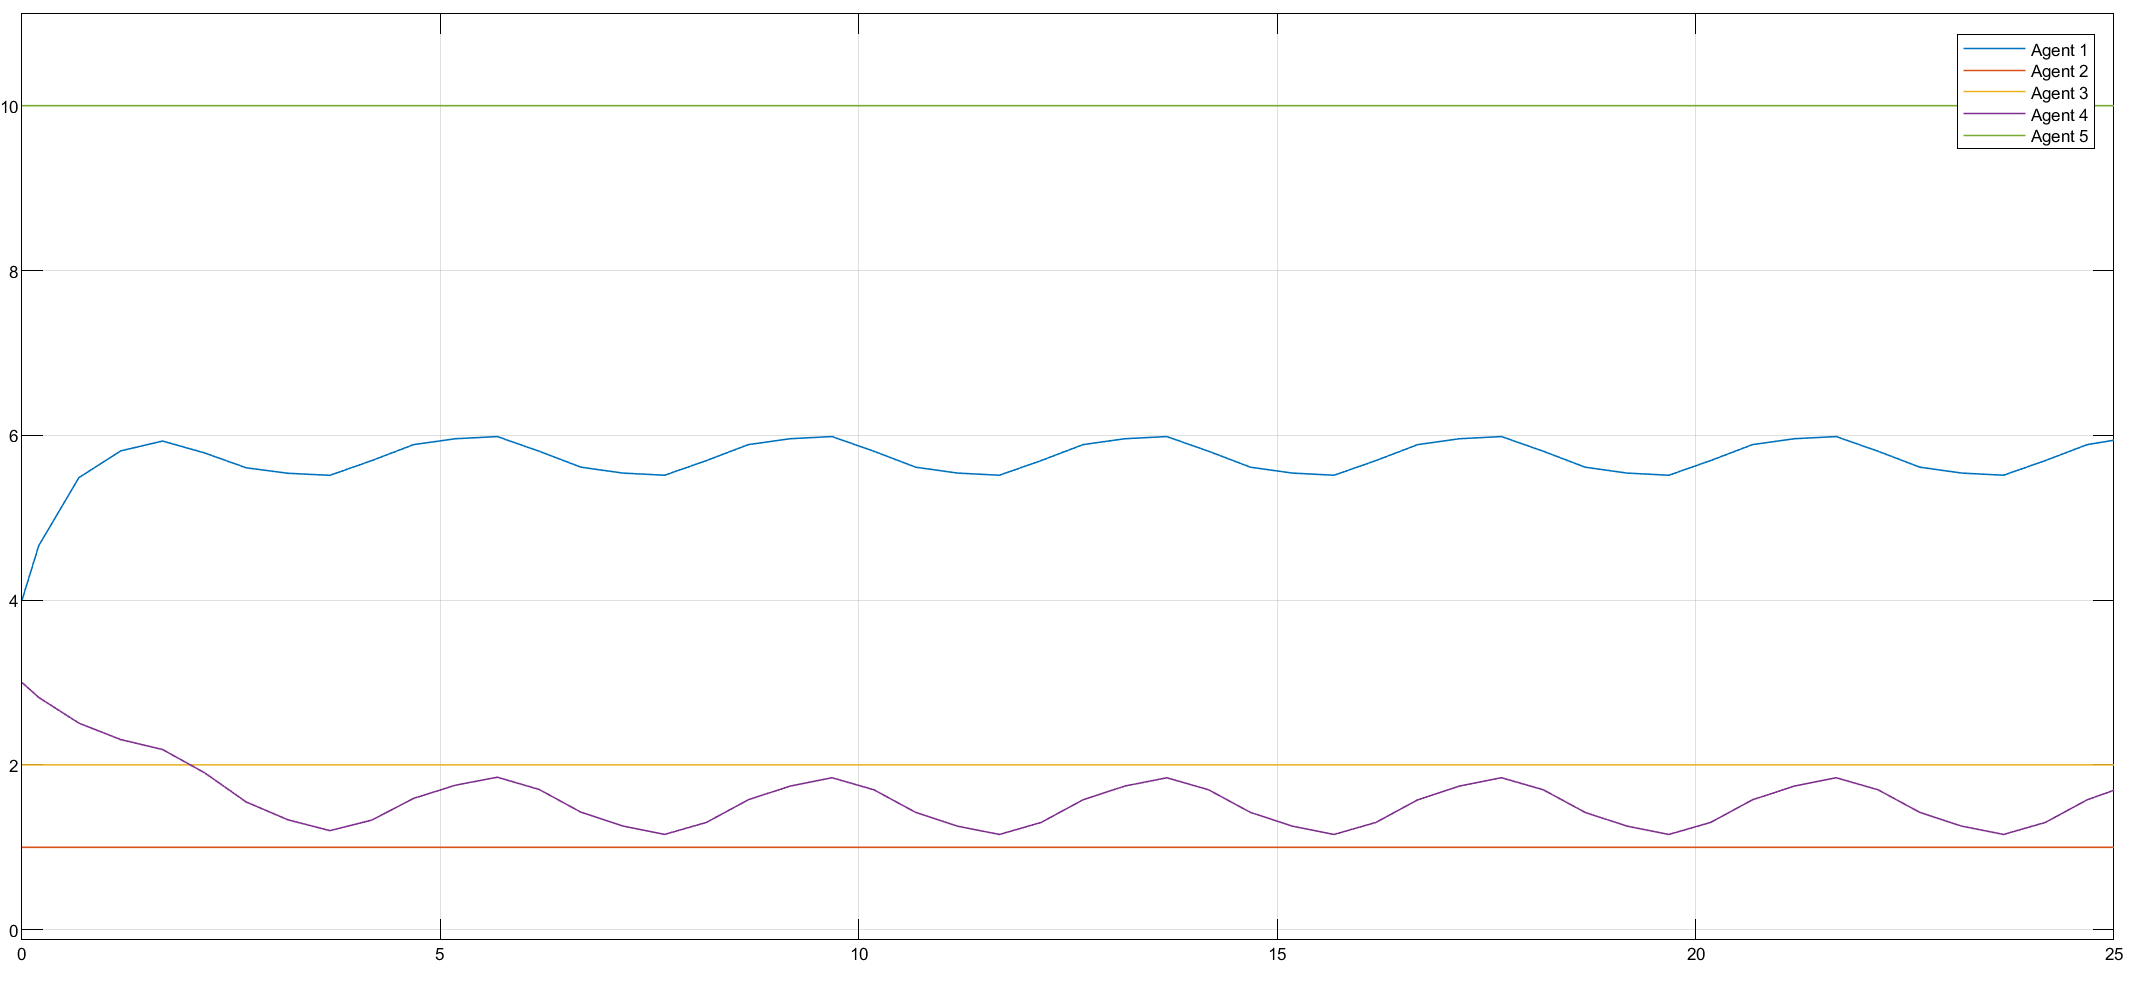

Diagram of the left topology (for dynamic input):

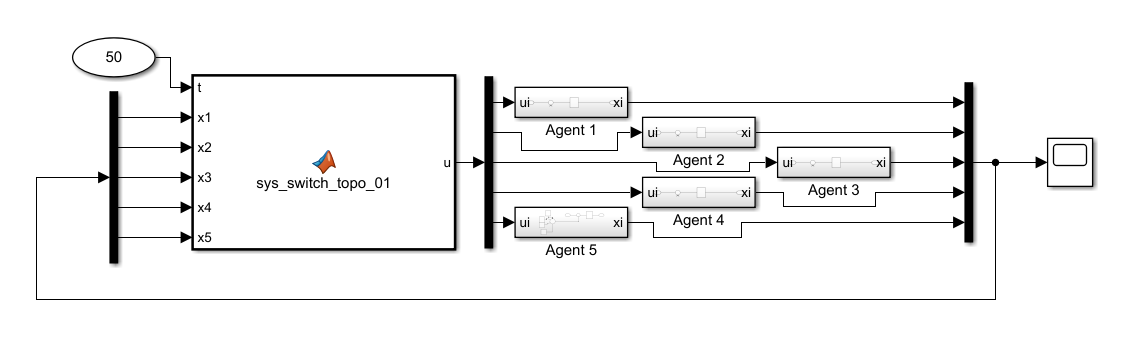

Each agent dynamics is implemented as follows:

and the leader dynamics:

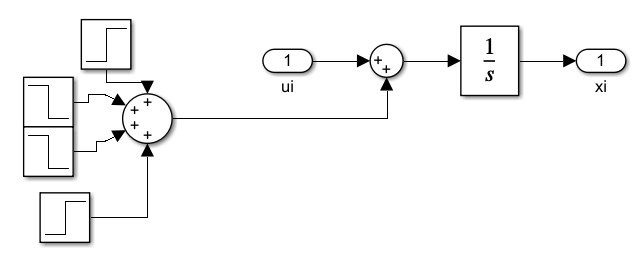

The leader is experiencing a variation in the input signal from 20 to 35 seconds. At t=20, a unit step function is applied, then at t=25, 0.5*unit_step is reduced. t=30 is when a unit step signal is reduced again anf finally, at t=35, +1/2*unit_step is addded.

The MAS dynamics could be implemented as follows. First, laplacian matrix is formed based on the given topology. Then the control signal is generated using `U = -LX`

In order to switch between topologies every 2s, we could use the `clock` block to access the simulation time. Therefore, passing the time into the function enables us to switch between topologies at any desired time using simple `if` statements.   

function u = sys_switch_topo_02(t, x1, x2, x3, x4, x5)

if rem(floor(t/2),2) == 0
    L = [2  0 -1  0 -1;
         0  0  0  0  0;
         0  0  0  0  0;
         0  0 -1 +1  0;
         0  0  0  0  0;
        ];

else
    L = [2 -1  0  0 -1;
         0  0  0  0  0;
         0  0  0  0  0;
         0 -1  0 +1  0;
         0  0  0  0  0;
        ];
end
    
states = [x1, x2, x3, x4 x5]';

u = -L*states;

end

Note that the initial conditions of the agents are set as follows: 4 , 1 , 2 , 3 , 10

You could see that the consensus is reached and all the followers have reached to the leader.

Diagram of the right topology (for dynamic input):

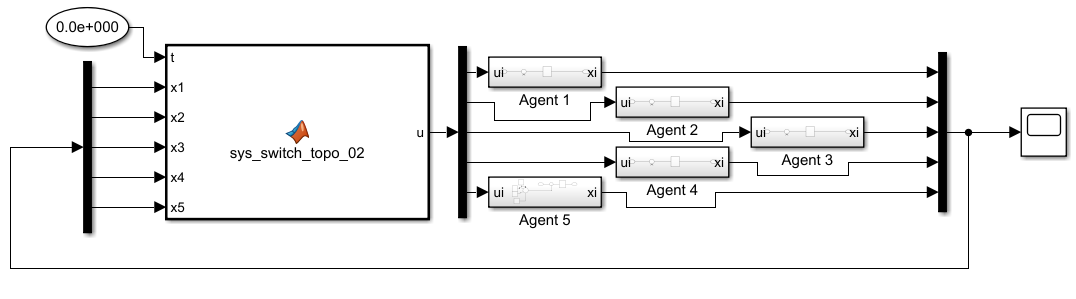

Each agent dynamics is implemented as follows:

and the leader dynamics:

The leader is experiencing a variation in the input signal from 20 to 35 seconds. At t=20, a unit step function is applied, then at t=25, 0.5*unit_step is reduced. t=30 is when a unit step signal is reduced again anf finally, at t=35, +1/2*unit_step is addded.

The MAS dynamics could be implemented as follows. First, laplacian matrix is formed based on the given topology. Then the control signal is generated using `U = -LX`

In order to switch between topologies every 2s, we could use the `clock` block to access the simulation time. Therefore, passing the time into the function enables us to switch between topologies at any desired time using simple `if` statements.   

function u = sys_switch_topo_02(t, x1, x2, x3, x4, x5)

if rem(floor(t/2),2) == 0
    L = [2  0 -1  0 -1;
         0  0  0  0  0;
         0  0  0  0  0;
         0  0 -1 +1  0;
         0  0  0  0  0;
        ];

else
    L = [2 -1  0  0 -1;
         0  0  0  0  0;
         0  0  0  0  0;
         0 -1  0 +1  0;
         0  0  0  0  0;
        ];
end
    
states = [x1, x2, x3, x4 x5]';

u = -L*states;

end

Note that the initial conditions of the agents are set as follows: 4 , 1 , 2 , 3 , 10

Since there is no jointly connected graph, we do not expect the MAS to reach the consensus and It has not.